QVec = []


QVec =

     []



for S0 = [ .0001 .0005 .0009]
L = 2000; %length of channel, meters (m)
b = 5;  %width of the bottom of the channel, meters (m)
  %slope of the bottom of the channel
n = 0.0138; %Manning's roughness coefficient for the bottom of the channel
g = 9.8; %acceleration due to gravity, m^2/s
h = 3.5; %water depth, meters (m)

%set up time and space vectors
dt = 0.61; % delta t, seconds (s)
t = 0:dt:50; %time vector
dx = 100; % delta a, meters (m)
x = 0:dx:L; %space vector

%pre-allocate Q matrix and A matrix
%Discharge (Q) matrix:
Q = zeros(length(x), length(t));
%set up boundary conditions for Q
Q0 = 3; %base flow of inflow hydrograph in m^3/s
Qp = 12; %peak flow of inflow hydrograph in m^3/s
tp = 10;
tb = 20;
mask = t < 10;
Q(1,mask) = Q0 + ((Qp-Q0)/(tp))*t(mask);
Q(:, 1) = Q0;
mask = t >= 10 & t < 20; 
Q(1,mask) = Q0 - ((Qp-Q0)/(tb-tp))*(t(mask)-tb);
mask = t >= 20;
Q(1,mask) = Q0;

% Cross Section Area (A) matrix:
A = ones(length(x), length(t));
A(:,1) = b*h;

%matrix with the same dimensions to keep track of Courant value
C = zeros(length(x), length(t));

%solve the equations
for j = 1:length(t)-1
    for i = 2:length(x)-1 

        R = A(i,j)/(2*h+b); %R is the hydraulic radius
        alpha = 2*(Q(i,j)/A(i,j)) + (((g*A(i,j))/b)+(Q(i,j)/A(i,j))^2)/((Q(i,j)/A(i,j))*((5/3)-(4/3)*(R/b)));
        beta = g*A(i,j)*(((Q(i,j)^2*n^2)/(A(i,j)*R^(4/3)))-S0);
        
        C(i,j) = (dt/dx) * alpha; %need to keep this below 1 to remain stable

        Q(i, j+1) = Q(i,j) - (dt/dx) * alpha * (Q(i,j)-Q(i-1,j)) + (beta)*dt;
        A(i, j+1) = A(i,j) - (dt/dx) * (Q(i, j+1)-Q(i-1,j+1));
    end
end

QVec = [ QVec ;Q(6,:)]


end

QVec =     3.0000    2.9957    2.9915    2.9871    2.9828    2.9785    3.4314    3.7065    4.0071    4.3130    4.6216    4.9327    5.2463    5.5625    5.8815    6.2034    6.5285    6.8569    7.1889    7.5246    7.8642    8.2080    8.5539    8.8972    9.2311    9.5484    9.8421   10.1053   10.3315   10.5140   10.6462   10.7208   10.7300   10.6645   10.5131   10.2618    9.8917    9.3758    8.6745    7.7482    6.5956    5.3140    4.1362    3.3456    3.0323    2.9809    2.9778    2.9776    2.9776    2.9776


QVec =     3.0000    2.9957    2.9915    2.9871    2.9828    2.9785    3.4314    3.7065    4.0071    4.3130    4.6216    4.9327    5.2463    5.5625    5.8815    6.2034    6.5285    6.8569    7.1889    7.5246    7.8642    8.2080    8.5539    8.8972    9.2311    9.5484    9.8421   10.1053   10.3315   10.5140   10.6462   10.7208   10.7300   10.6645   10.5131   10.2618    9.8917    9.3758    8.6745    7.7482    6.5956    5.3140    4.1362    3.3456    3.0323    2.9809    2.9778    2.9776    2.9776    2.9776
    3.0000    2.9539    2.9076    2.8611    2.8144    2.7676    3.3310    3.5326    3.8166    4.1077    4.4016    4.6977    4.9961    5.2969    5.6004    5.9066    6.2157    6.5279    6.8434    7.1624    7.4850    7.8115    8.1395    8.4634    8.7761    9.0696    9.3368    9.5704    9.7638    9.9103   10.0030   10.0344    9.9962    9.8787    9.6698    9.3539    8.9097    8.3053    7.4929    6.4328    5.1676    3.9216    3.0703    2.7836    2.7670    2.7678    2.7677    2.7677    2.7677  

QVec =     3.0000    2.9957    2.9915    2.9871    2.9828    2.9785    3.4314    3.7065    4.0071    4.3130    4.6216    4.9327    5.2463    5.5625    5.8815    6.2034    6.5285    6.8569    7.1889    7.5246    7.8642    8.2080    8.5539    8.8972    9.2311    9.5484    9.8421   10.1053   10.3315   10.5140   10.6462   10.7208   10.7300   10.6645   10.5131   10.2618    9.8917    9.3758    8.6745    7.7482    6.5956    5.3140    4.1362    3.3456    3.0323    2.9809    2.9778    2.9776    2.9776    2.9776
    3.0000    2.9539    2.9076    2.8611    2.8144    2.7676    3.3310    3.5326    3.8166    4.1077    4.4016    4.6977    4.9961    5.2969    5.6004    5.9066    6.2157    6.5279    6.8434    7.1624    7.4850    7.8115    8.1395    8.4634    8.7761    9.0696    9.3368    9.5704    9.7638    9.9103   10.0030   10.0344    9.9962    9.8787    9.6698    9.3539    8.9097    8.3053    7.4929    6.4328    5.1676    3.9216    3.0703    2.7836    2.7670    2.7678    2.7677    2.7677    2.7677  

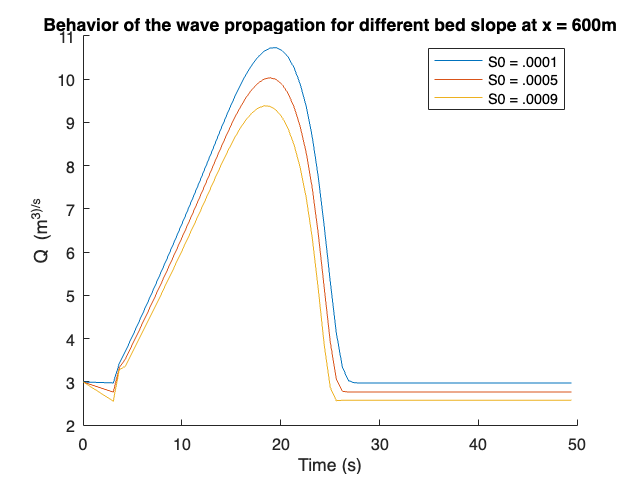


figure 
hold on
plot(t, QVec(1,:))
plot(t, QVec(2,:))
plot(t, QVec(3,:))
xlabel('Time (s)')
ylabel('Q (m^3)/s')
title('Behavior of the wave propagation for different bed slope at x = 600m')
legend('S0 = .0001', 'S0 = .0005', 'S0 = .0009')